load memories.dat

memories

Unrecognized function or variable 'memories'.

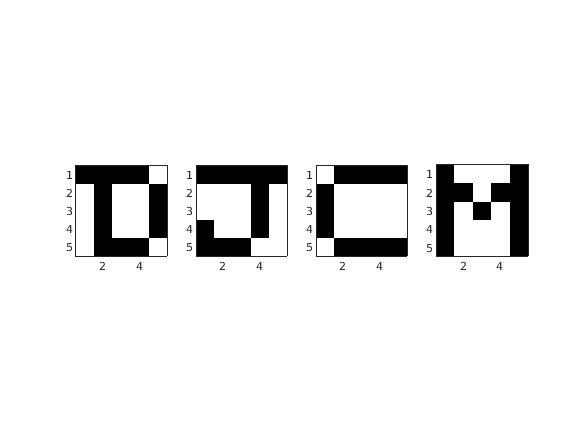

% Plot the stored memories
colormap gray; 
cmap = colormap; 
cmap = flipud(cmap); 
colormap(cmap);

figure(1); clf
N = 4 % define number of stored memories

N = 4


storedMems = memories(1:N, :)

Unrecognized function or variable 'memories'.

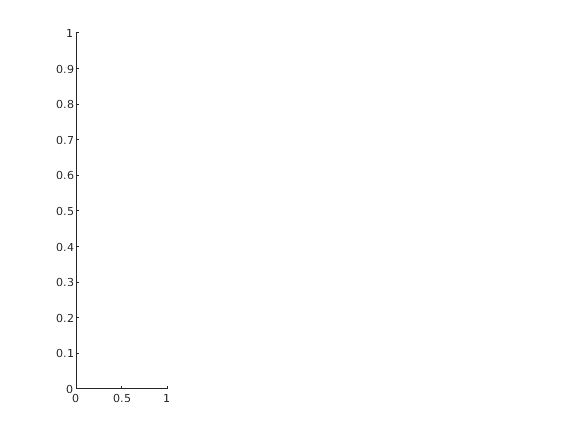

Unrecognized function or variable 'storedMems'.

for i = 1:N
    subplot(1, N, i)
    % 1 = num grid rows
    % N = num grid cols
    % i = grid position for new axes
    
    imagesc(reshape(storedMems(i, :), 5, 5)'); 
    axis square;
end

% Now creating variable T (targets) by definition of T

% Setting memories to {-1, 1} instead
% of {0, 1}
I = find(storedMems == 0);
%T = storedMems; 
%T(I) = -1;
%T
storedMems(I) = -1; 

% Plotting again for visual
for i = 1:N
    subplot(1, N, i)
    % 1 = num grid rows
    % N = num grid cols
    % i = grid position for new axes
    
    imagesc(reshape(storedMems(i, :), 5, 5)'); 
    axis square;
end

%% why the same?

% Doing algorithm by lab 5 solution: 
W_temp = storedMems' * storedMems; % Hebb rule

% Initialize X to a corrupted memory (the exercise)
n = 1 % memory number

n = 1

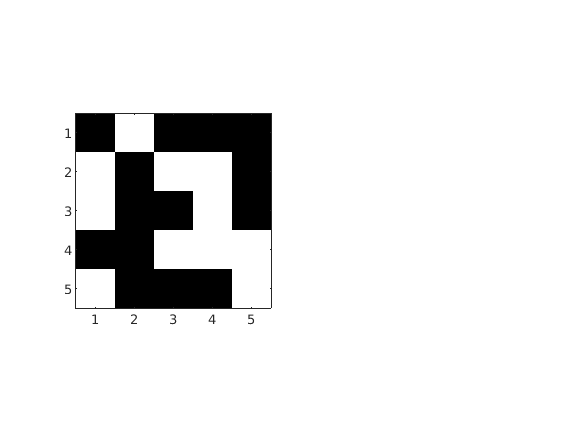

x = storedMems(n, :)';
% Corrupting some random bits
x(16, 1) = -x(16, 1);
x(2,1)  = -x(2,1);
x(5,1)  = -x(5,1);
x(20,1)  = -x(20,1);
x(13,1)  = -x(13,1);

% Plotting the bad state
figure(2); clf
%colormap(cmap);
subplot(1,2,1)
imagesc(reshape(x,5,5)');
axis square;

 % Algo continued: Synchronous updates of Hopfield
 newx = x; 
 for i = 1:2
     newx = thresh(W_temp * x);
 end

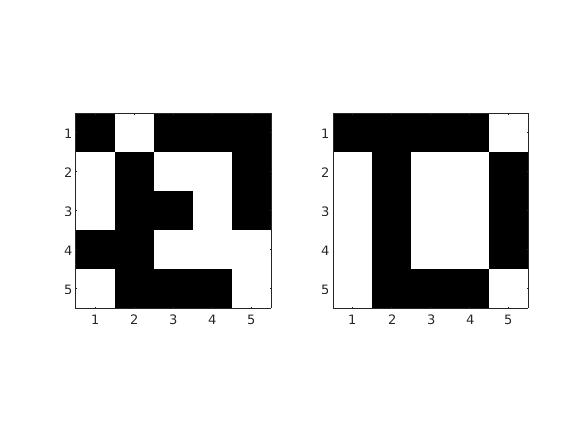

% Plot nearest stable state
figure(2)
subplot(1,2,2)
imagesc(reshape(newx,5,5)');
axis square

## CONCLUSION: the corrupted initial state (left) has converged to a stored memory after two iterations!

## Doing the above Memory Restore using my function

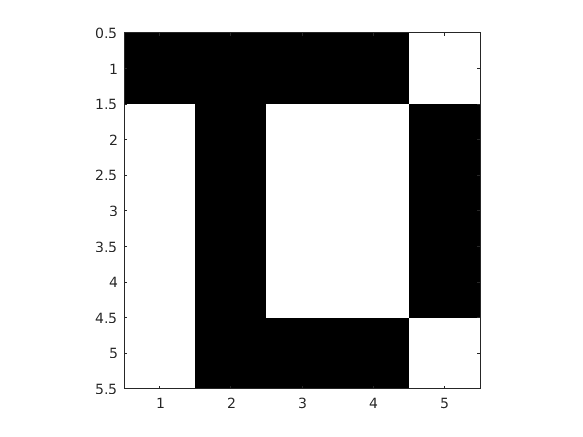

% making the matrix
Xcorrupt = X;
Xcorrupt(n, :) = x; 
restoreMemoryTest(X, Xcorrupt, n)


% YAY: My algorithm worked like in the lab to recover initial state.

## Doing hebbian learning using my function


W_heb = hopfieldHebbianLearning(X, 0.01)

W_heb =     0.0100    0.0100    0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100    0.0100    0.0100   -0.0100
    0.0100    0.0100    0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100    0.0100    0.0100   -0.0100
    0.0100    0.0100    0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100    0.0100    0.0100   -0.0100
    0.0100    0.0100    0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100   -0.0100   -0.0100    0.0100   -0.0100    0.0100    0.0100    0.010

## Doing Gradient Descent for hopfield (better then hebbian says page 516 in Mackay)

W_grad = hopfieldGradientDescent(X, T, 0.01, 0.01);

W_grad

W_grad =     0.0200   -0.1999   -0.1999   -0.1999   -0.1999   -2.2979    2.0979   -2.0982    2.0980    2.0979   -2.2979   -0.0000   -0.0000    0.0000    2.0979   -0.1999   -0.0000   -2.0982    0.0000    2.0979    2.0980   -0.1999   -0.1999   -2.2979   -2.2979
   -0.1999    0.0200    4.1959    4.1959   -0.1999   -2.2979   -2.2979   -2.0978   -2.2979   -2.2979   -2.2979    0.0000   -4.3958   -0.0000   -2.2979   -0.1999    0.0000   -2.0978   -0.0000   -2.2979   -2.2979    4.1959    4.1959    2.0980   -2.2979
   -0.1999    4.1959    0.0200    4.1959   -0.1999   -2.2979   -2.2979   -2.0978   -2.2979   -2.2979   -2.2979    0.0000   -4.3958   -0.0000   -2.2979   -0.1999    0.0000   -2.0978   -0.0000   -2.2979   -2.2979    4.1959    4.1959    2.0980   -2.2979
   -0.1999    4.1959    4.1959    0.0200   -0.1999   -2.2979   -2.2979   -2.0978   -2.2979   -2.2979   -2.2979    0.0000   -4.3958   -0.0000   -2.2979   -0.1999    0.0000   -2.0978   -0.0000   -2.2979   -2.2979    4.1959    4.1959    2.09